**Read input image**

img = imread('f18.tif');
img = im2double(img); % Convert to double for processing

**Display original image**

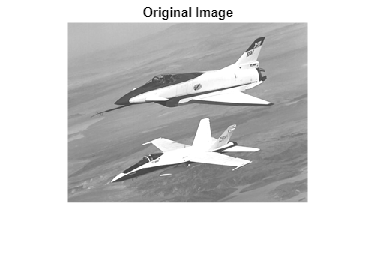

resized_img = imresize(img, 0.5);

figure;
imshow(resized_img);
title('Original Image');

**Add salt and pepper noise with probabilities Pa = Pb = 0.1**

noisy_img = imnoise(img, 'salt & pepper', 0.1);

**Apply 3x3 Median Filter - First Pass**

filtered_1 = medfilt2(noisy_img, [3 3]);

**Apply 3x3 Median Filter - Second Pass**

filtered_2 = medfilt2(filtered_1, [3 3]);

**Apply 3x3 Median Filter - Third Pass**

filtered_3 = medfilt2(filtered_2, [3 3]);

**Display results with proper spacing**

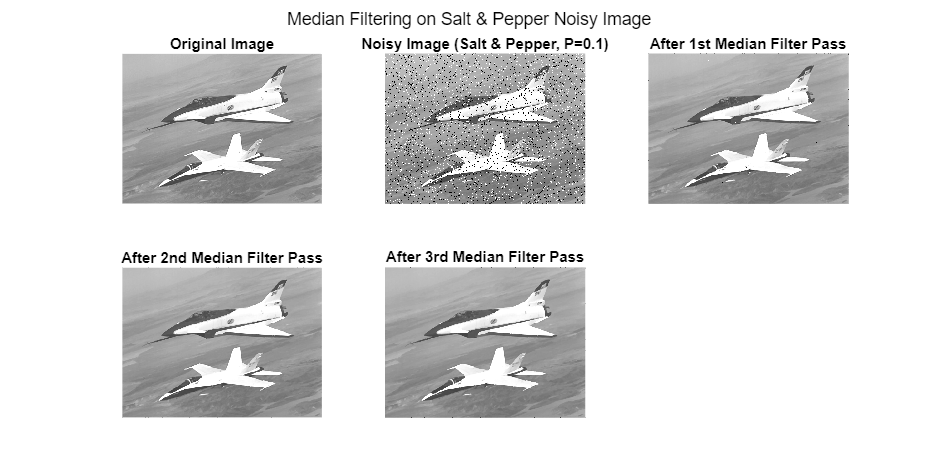

figure;
set(gcf, 'Position', [100, 100, 1000, 500]); % Set figure size

subplot(2,3,1), imshow(img), title('Original Image', 'FontSize', 12);
subplot(2,3,2), imshow(noisy_img), title('Noisy Image (Salt & Pepper, P=0.1)', 'FontSize', 12);
subplot(2,3,3), imshow(filtered_1), title('After 1st Median Filter Pass', 'FontSize', 12);
subplot(2,3,4), imshow(filtered_2), title('After 2nd Median Filter Pass', 'FontSize', 12);
subplot(2,3,5), imshow(filtered_3), title('After 3rd Median Filter Pass', 'FontSize', 12);

sgtitle('Median Filtering on Salt & Pepper Noisy Image', 'FontSize', 14); % Set main title